# Image Geometries and Transforms

MATLAB provides powerful geometric transformation and image resampling capabilities. The following is intended to clarify their use.

- An image is stored in an array and array indices use (row, column) order.

- The top left array element is (1,1) and the row number increases as you go down.

- Coordinates, plots and geometric transforms specify values in (x,y) order.

- 'Spatial referencing' links the elements of an array to a coordinate system. 

- The default MATLAB intrinsic spatial coordinates are such that y increases as you go down. This means y aligns with image row number. Note though that coordinates are handled as (x,y) i.e. column,row. The help page on Image Coordinate Systems is useful.

- MATLAB provides spatial referencing functons to link intrinsic to world coordinates, but the two coordinate systems have to be aligned.

- DICOM describes spatial referencing by specifying the position of the centre of the top left voxel (`ImagePositionPatient)`, the directions of the image rows and columns (`ImageOrientationPatient)` and the `PixelSpacing.` These use the 3D coordinate system with dimensions **Left, Posterior, Head** (LPH) This allows a spatial referencing where the patient coordinate system is not parallel to the image. It is also simple to use vector addition to find the 3D position of any image voxel. 

- The (row,column) vs (x,y) ordering and y increasing as you go down can cause confusion and a temptation to negate an axis, use flipdim or transpose data. Usually these are not required, except for a permuting of dimensions 1 and 2 at the 'interface' between coordinates and images. Although the intrinsic spatial coordinates have y going down, it is still a valid right-handed system and all transform arthimetic works without having to negate y or other 'nasties'.

- When geometric transformations are described in MATLAB by matrices (e.g. an affine matrix), the main functions assume a vector-matrix product (not matrix-vector) e.g. `new_coord = old_coord * A`  with the coordinates as a row vector in homogeneous form (extra last element of 1). This means the elements of the matrix that represent translations are along the bottom row of the affine transformation matrix. There are helpful functions to take care of this e.g. `transformPointsForward`

- Geometric transforms can be encapsulated in a `tform`. Note there are class and structure forms for `tform `with newer functions such as `imwarp` using the class version.

- The documentation for functions such as `maketfrom`, `tformarray`, `makeresampler` is sparse, but there is some useful generic help in `imwarp` (at the end), in [web(fullfile(docroot, 'images/spatial-referencing.html'))](http://web(fullfile(docroot, 'images/spatial-referencing.html'))).

Loading and plot an image. Note the y-axis - this is the intrinsic coordinate system.

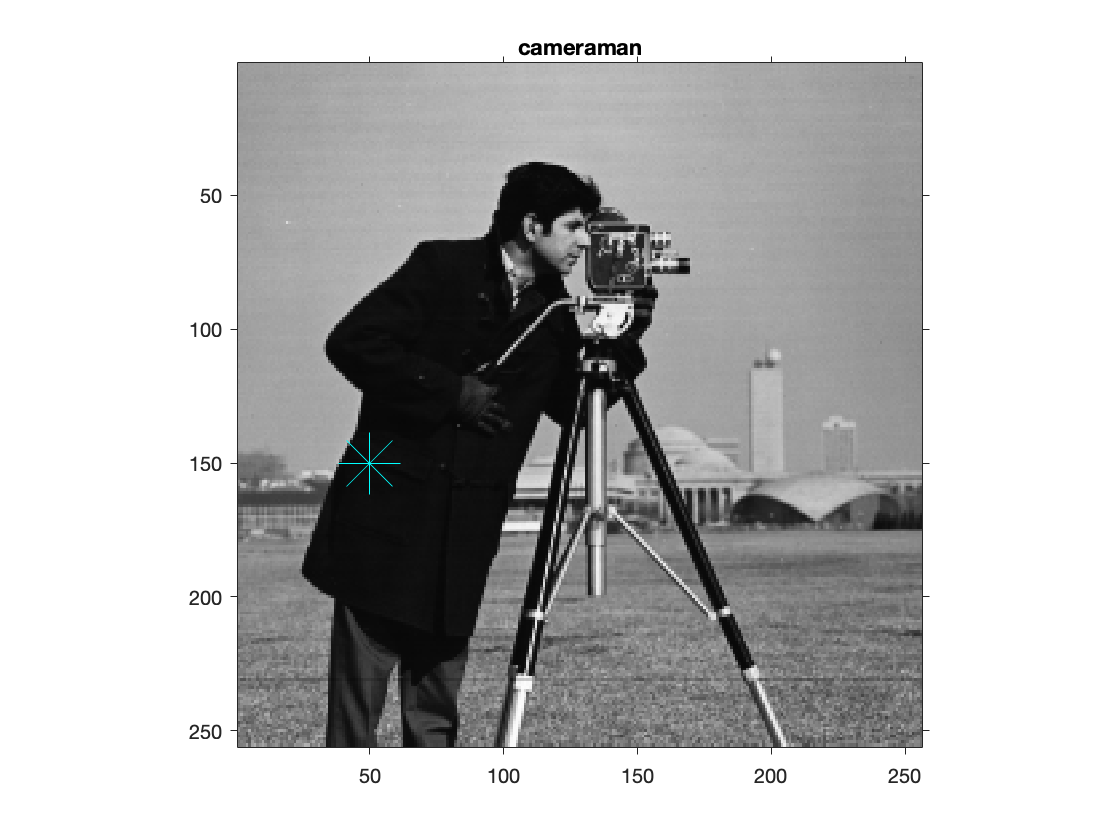

I = imread('cameraman.tif');
iptsetpref('ImshowAxesVisible','on'), iptsetpref('ImshowBorder', 'loose')
imshow(I), title('cameraman'), hold on
plot(50,150,'c*','MarkerSize',30) % plot(x,y) note y increases 
                    % going down in this mage instrinsic coordinate system
hold off

Apply a rigid transformation, using `imwarp.` `The` transform applies to the intrinsic spatial coordinates where y is down. All normal coordinate operations can be performed. 

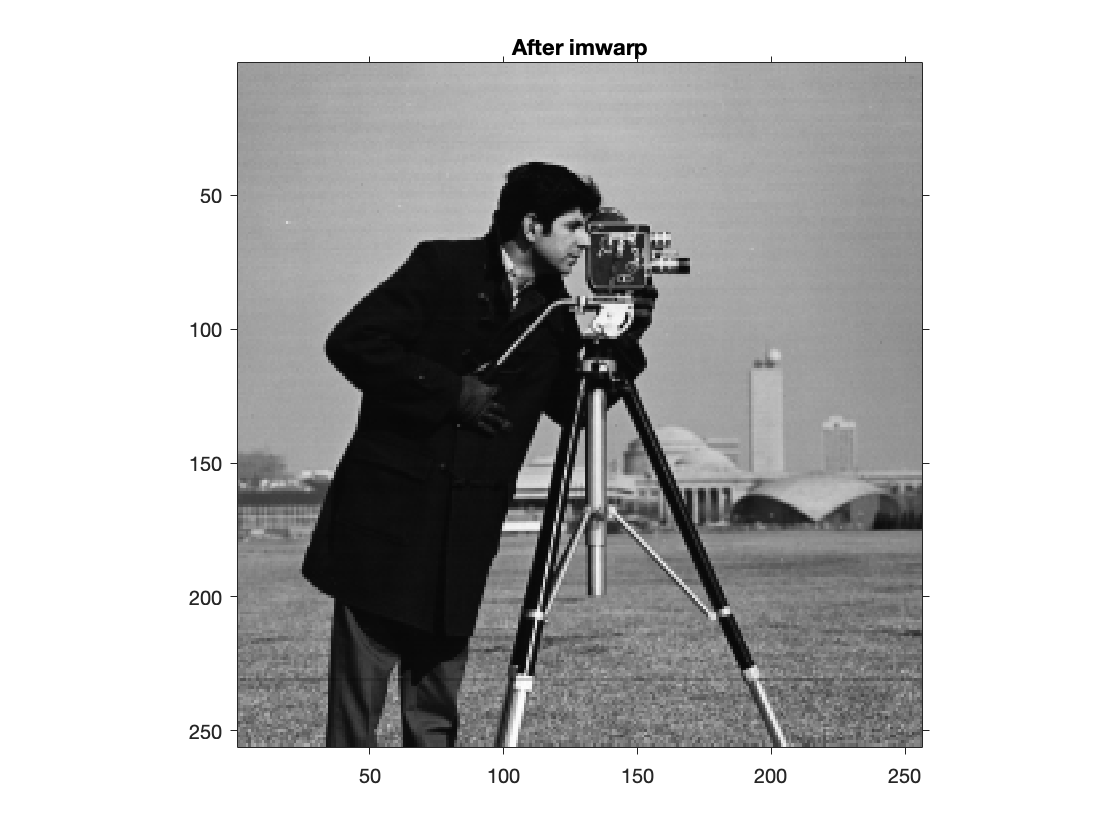

dx = 40 ; dy = 20 ;

tform = affine2d([ ...
    1  0  0; ...
    0  1  0; ...
    dx dy 1]) ;

Iout = imwarp(I,tform) ; 
figure, imshow(Iout), title('After imwarp')

However, we **see no change in the image** - although the image is at a different place in the real world,  the image itself looks the same (somewhat like a camera following an object).

For affine transformations, we can specify to `imwarp` an `'OutputView'`. Using `'SameAsInput'`, we get the image shifting, perhaps as expected:

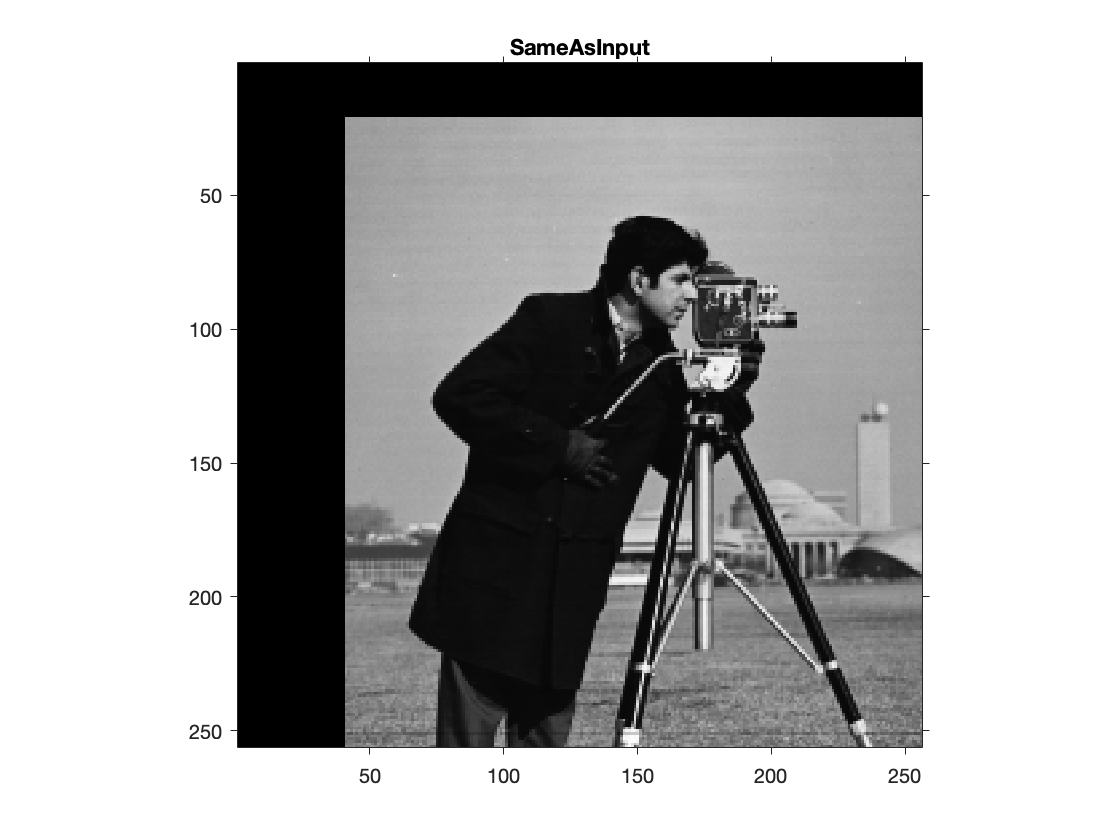

Rsiout = affineOutputView(size(I),tform,'BoundsStyle','SameAsInput') ;
IoutSameAsInput = imwarp(I,tform,'OutputView',Rsiout) ;
imshow(IoutSameAsInput), title('SameAsInput')

and using `'FollowOutput'`, we follow the output:

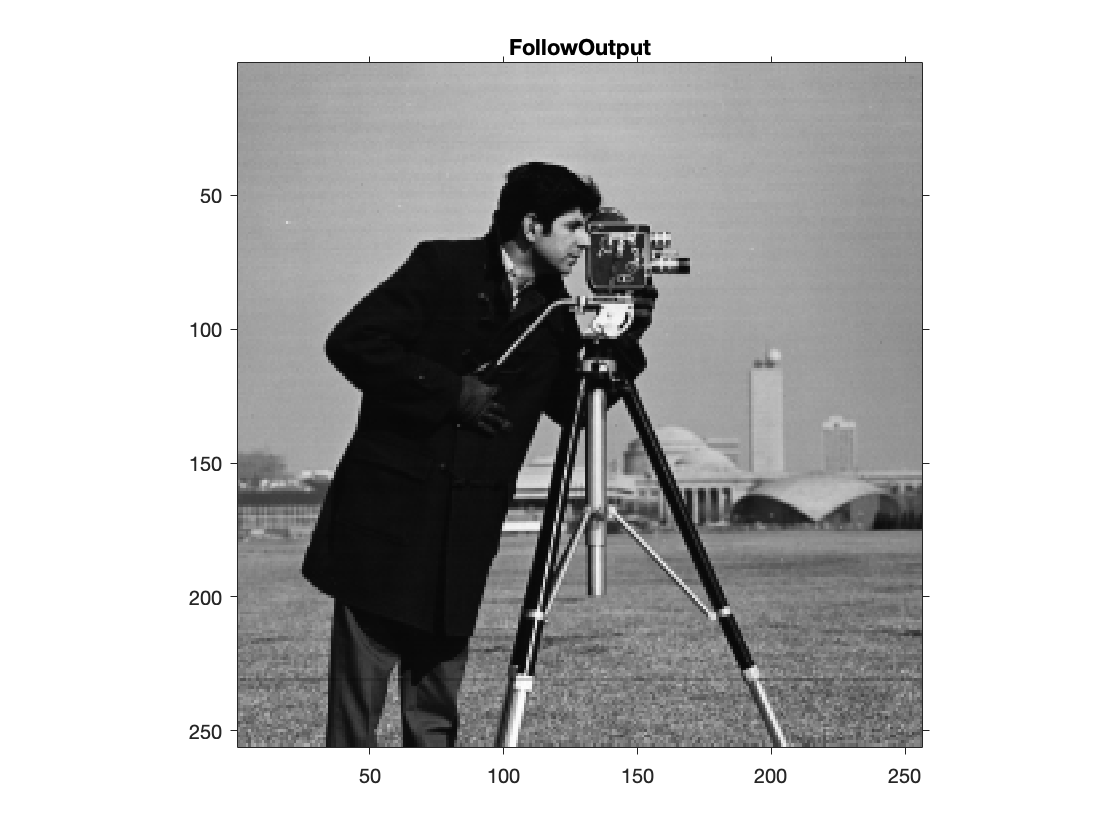

Rfoout = affineOutputView(size(I),tform,'BoundsStyle','FollowOutput') ;
IoutFollowOutput = imwarp(I,tform,'OutputView',Rfoout) ;
imshow(IoutFollowOutput), title('FollowOutput')

for the version of `imshow` in the ImageProcessingToolbox, an alternative is to pass in a spatial referencing object: to get the full image with the modified axis labels:

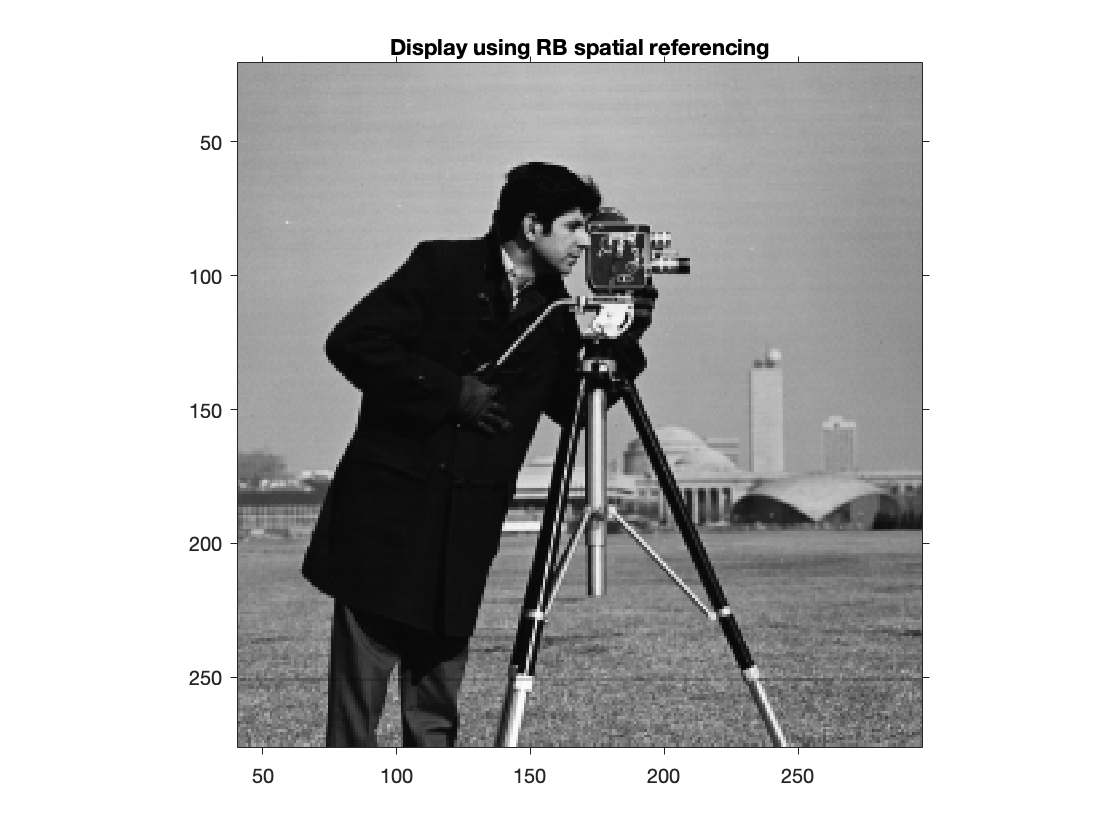

RA = imref2d(size(I)) ; % set up spatial referencing object for original
[Inew, RB] = imwarp(I,RA,tform) ; 
imshow(Inew, RB), title('Display using RB spatial referencing')

Note that the axis labelling is 'correct'  if we also pass in either a spatial referencing object or an `'OutputView'` to `imwarp`. What we see may differ, but the labelling seems to be correct.

Rather than a `tform`, one can provide `imwarp` with displacement fields specified in the intrinsic coordinate system:

D = zeros(size(I,1), size(I,2),2) ;
D(:,:,1) = dx ; % x displacements
D(:,:,2) = dy ; % y displacements

B = imwarp(I,D) ;
imshow(B), title('Applied D')

The displacements D can come from `imregdemons. "`The displacement vectors at each pixel location map locations from the `fixed` image grid to a corresponding location in the `moving `image."  It seems that `imwarp` assumes this convention and as the normal use of `imwarp` is to transform `moving` to the space of `fixed`, it applies the opposite of D, i.e. here it moved the image left and up.

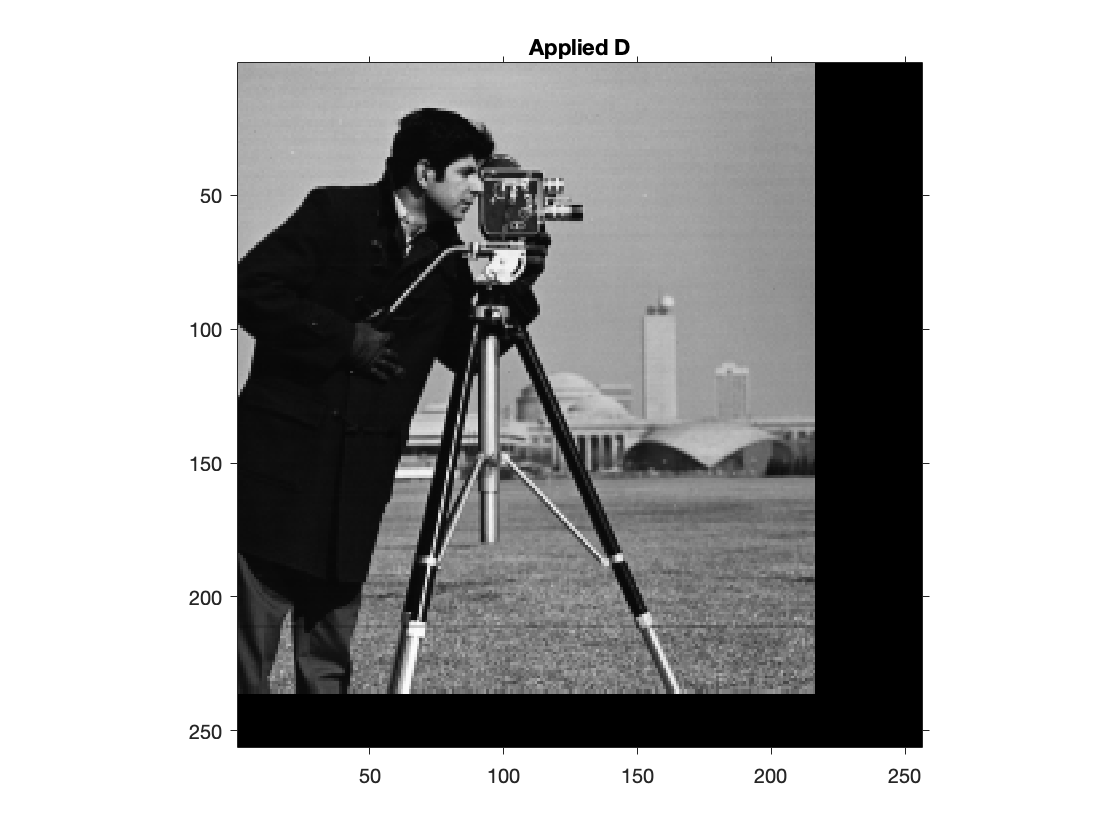

fixed = I ; moving = IoutSameAsInput ;
[Dreg,moving_reg] = imregdemons(moving,fixed,[400 300 200]) ;

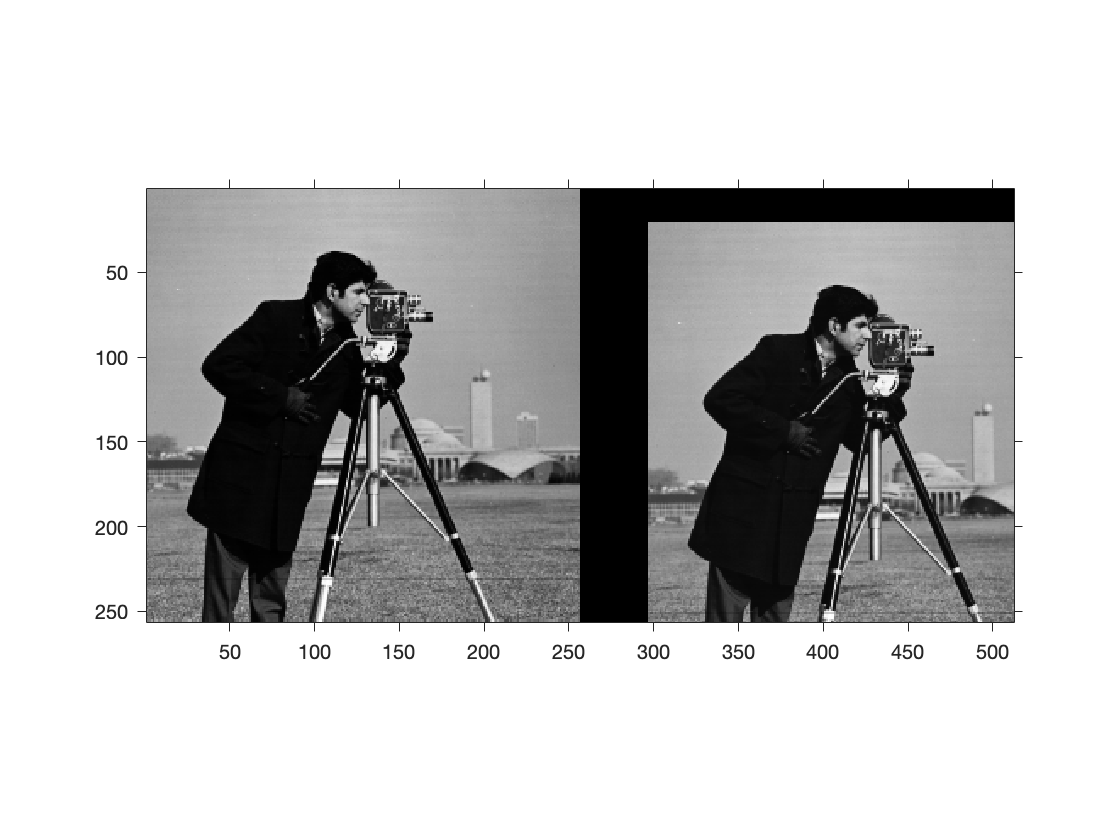

imshowpair(fixed,moving,'montage')

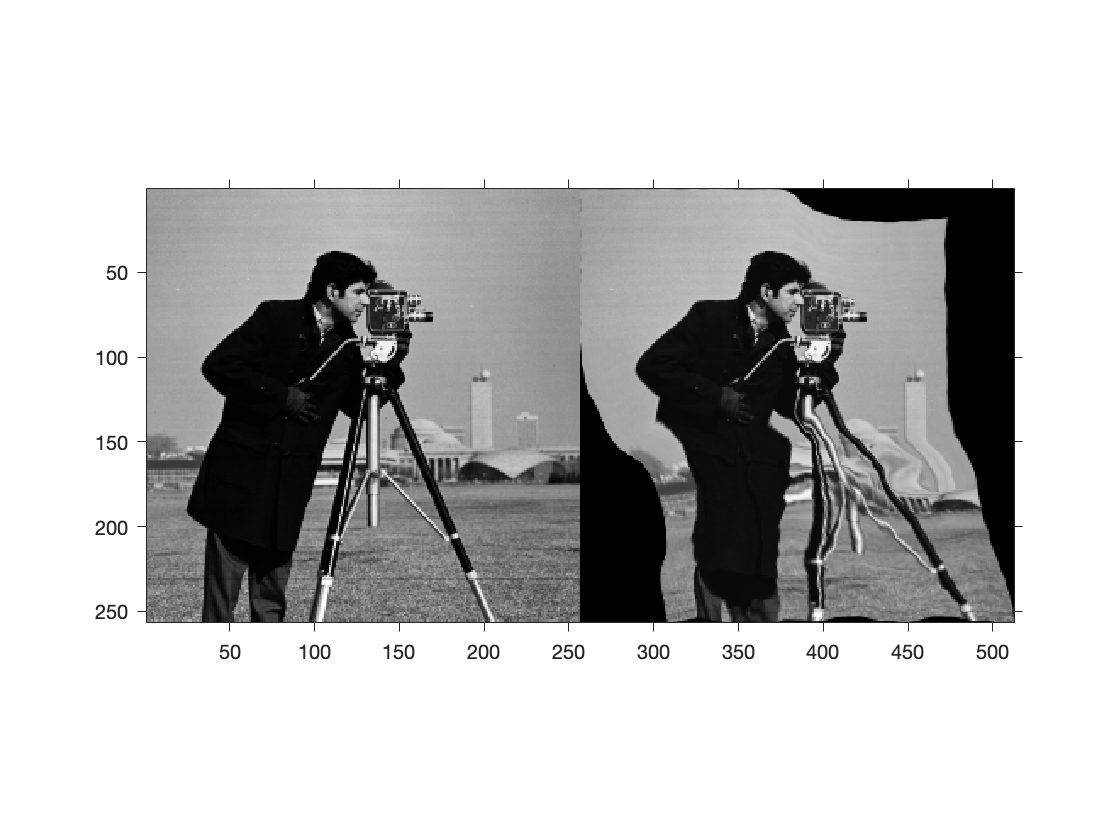

imshowpair(fixed,moving_reg,'montage')

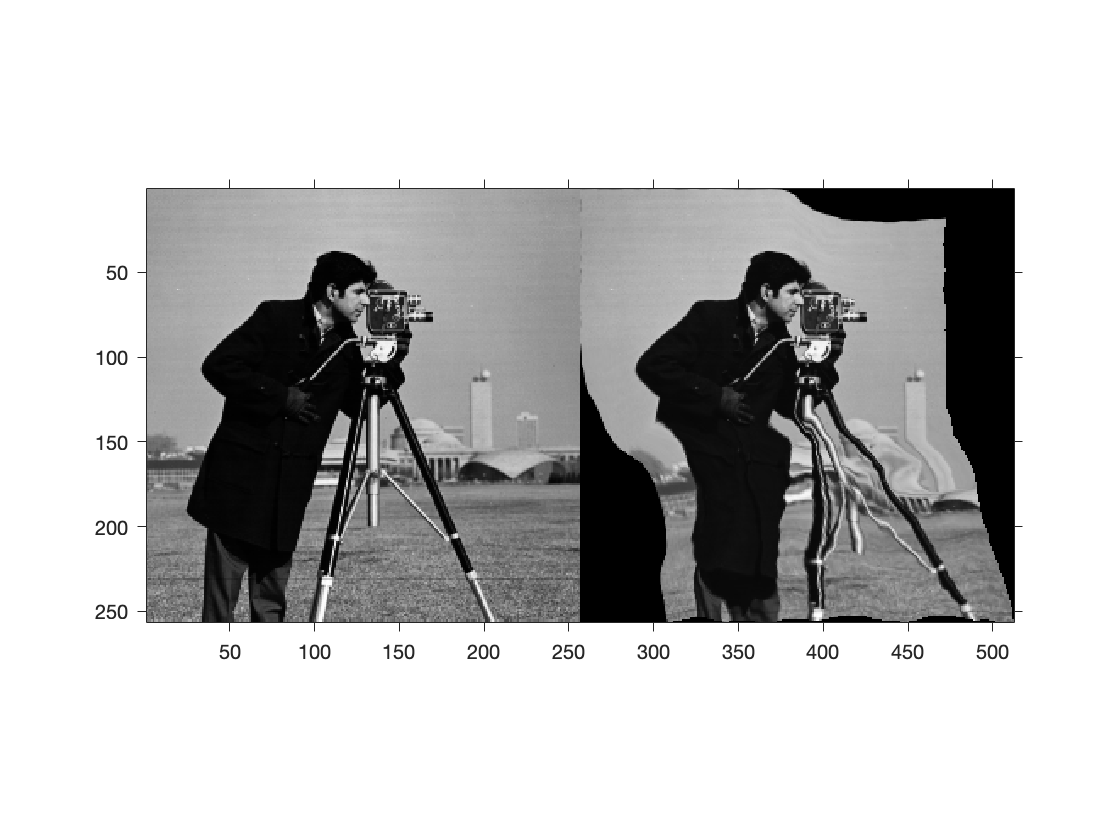


Fwarp = imwarp(moving,Dreg) ;
imshowpair(fixed,Fwarp,'montage')

`moving_reg = imwarp(moving, Dreg)`  (confirmed in `imregdemons`)

The interpretation of `tforms` in `imwarp` is that they map a moving image to a fixed.

It seems that `imwarp` applies the **forward** transform if it is supplied an affine `tform` or a user-specified inverse function from `geometricTransform2d`  

### Using geometricTransform2d 

This lets the user specify the geometric transform function. Note the convention that input space is UV and the output XY.

XY = [10 15;11 32;15 34;2 7;2 10]       % points in output space

XY =     10    15
    11    32
    15    34
     2     7
     2    10


inversefn = @(c) [c(:,1)+10, c(:,2)] ;  % inv transform
tform = geometricTransform2d(inversefn);
UV = transformPointsInverse(tform,XY)   % points in input space

UV =     20    15
    21    32
    25    34
    12     7
    12    10


`tranformPointsInverse` needs a `tform` where the inverse is either specified by the user explicitly as above, or can be inferred if `tform` comes from say `affine2d`. 

It can deal with points in separate X,Y arrays, or packed.

Using scale is a good way to look at transformation directions as it is free from sign confusions.

- Set the inverse function to halve the x coordinate.

- Apply to an image using `imwarp`

- We get an **expanded** image!

- Set an affine (forward) transform to have a scale factor 0.5, image shrinks as expected.

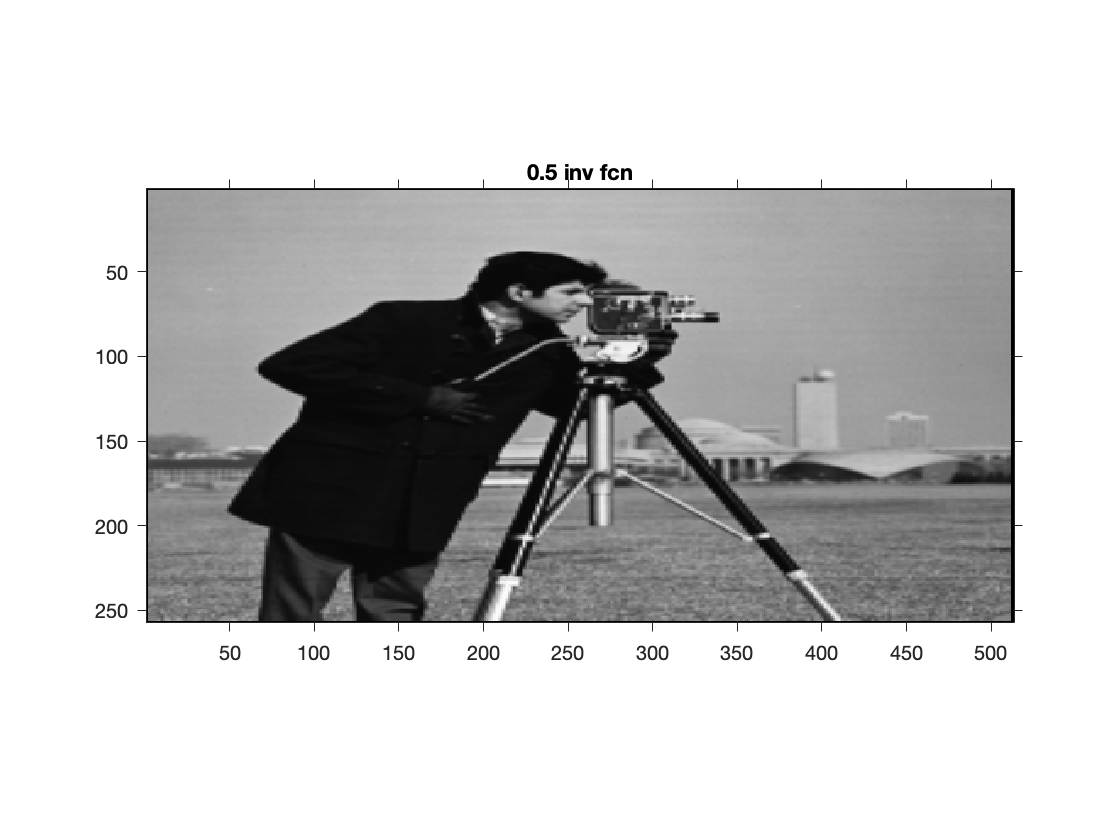

inversefn = @(c) [c(:,1)/2, c(:,2)] ;
tform1 = geometricTransform2d(inversefn);
Iout1 = imwarp(I, tform1) ;
figure, imshow(Iout1), title('0.5 inv fcn') % Image looks stretched

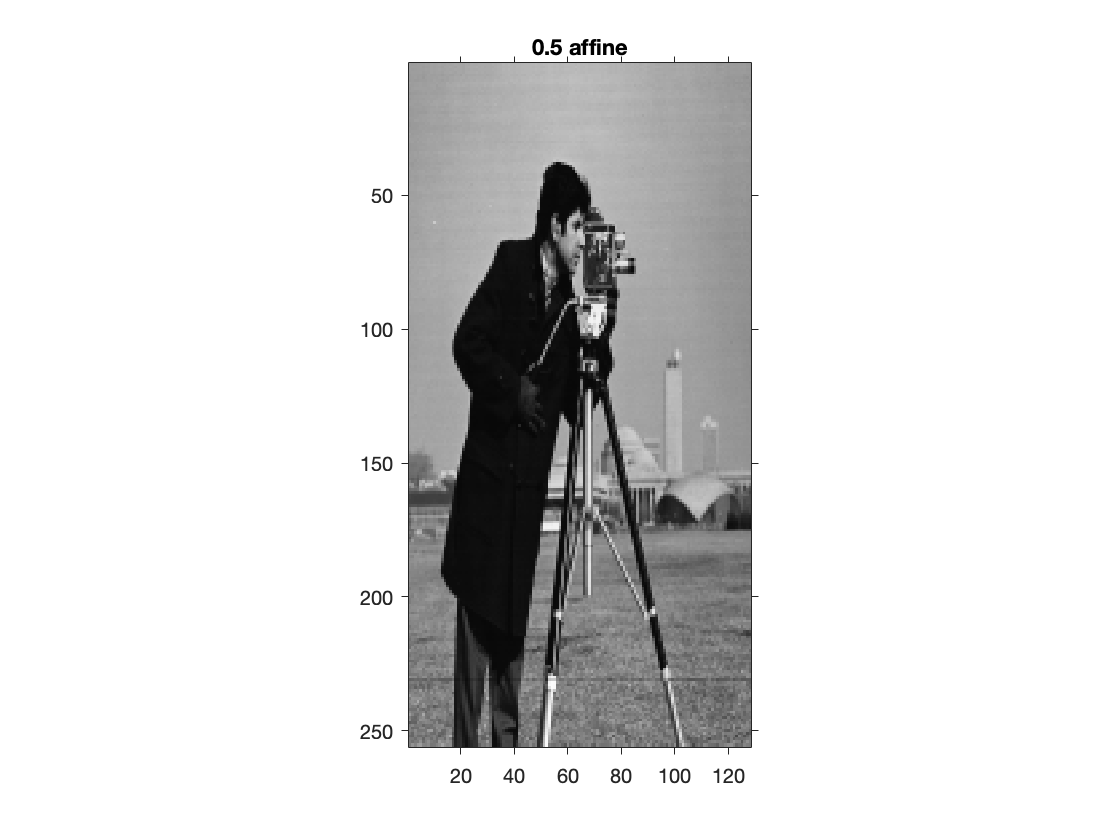


tform2 = affine2d([ ...
    0.5 0 0 ; ...
    0   1 0 ; ...
    0   0 1 ]) ;

Iout2 = imwarp(I, tform2) ;
figure, imshow(Iout2), title('0.5 affine') % image looks shrunk

So, `imwarp` effectively applies the forward transform (even though it doesn't have it specified in the first case above).

In the context of registration, the usual interpretation is for the MATLAB function to return the transform that maps from `moving` to `fixed`, so that the registered image is 

`movingReg = imwarp(moving, tform) ;`

It seems that the displacement fields map `fixed` to `moving` so `imwarp` uses the inverse?

Note the axes from using plot-type functions have y-up.

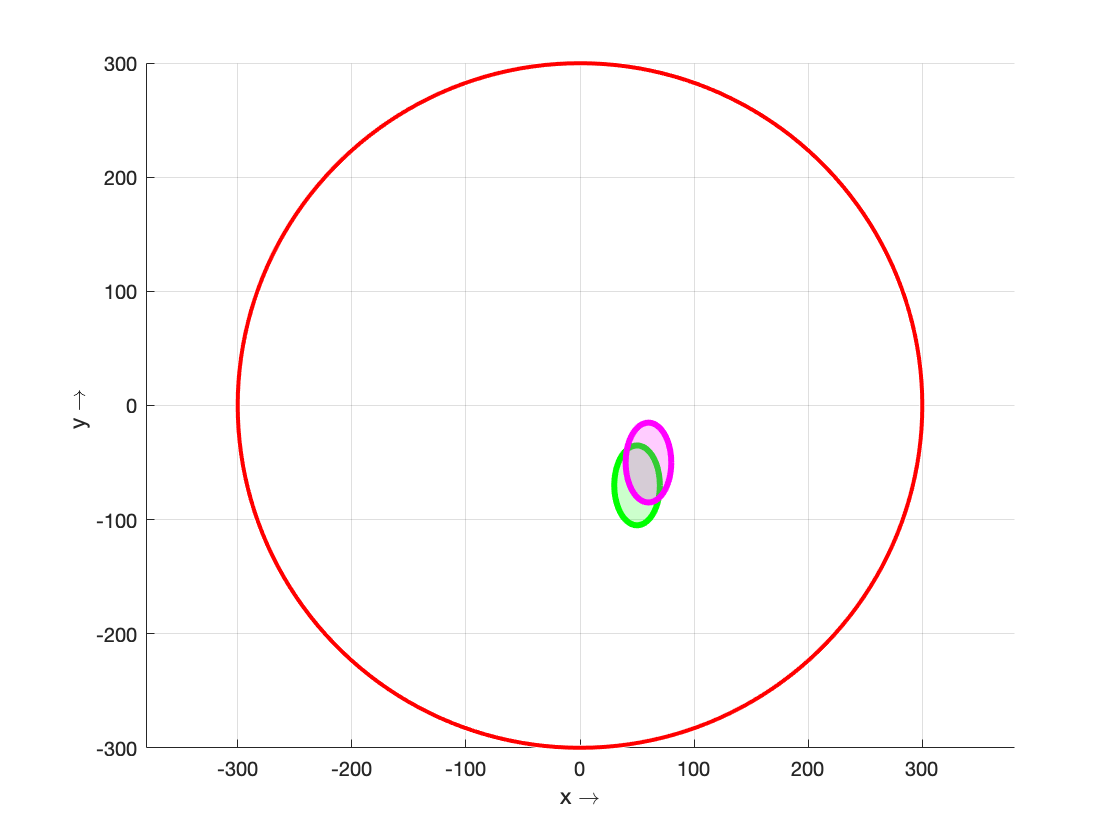

% Here, everything is [x,y] with y up
figure('Name','Scanner')
center = [50 -70]; semiaxes = [20 35] ; rad = 300 ; sft = [10  20] ;

viscircles([0 0],rad); grid on , axis equal
h = drawellipse('Center',center,'SemiAxes',semiaxes,'Color','g','InteractionsAllowed' ,'none');
h = drawellipse('Center',center + sft,'SemiAxes',semiaxes,'Color','m','InteractionsAllowed' ,'none');
xlabel('x \rightarrow'), ylabel('y \rightarrow ')

Now, let's do a similar thing using the `phantom` command so that we can get an image (not a plot) and perform image registration. Confusingly, in `phantom`, the ellipses are defined on a [-1,1] axis scale and with y positive going up. Conceptually, it's like the ellipses are defined on a normal Cartesian plot with axes having range [-1,1] and taking a photo to get an image (with y going down in default coordinates).

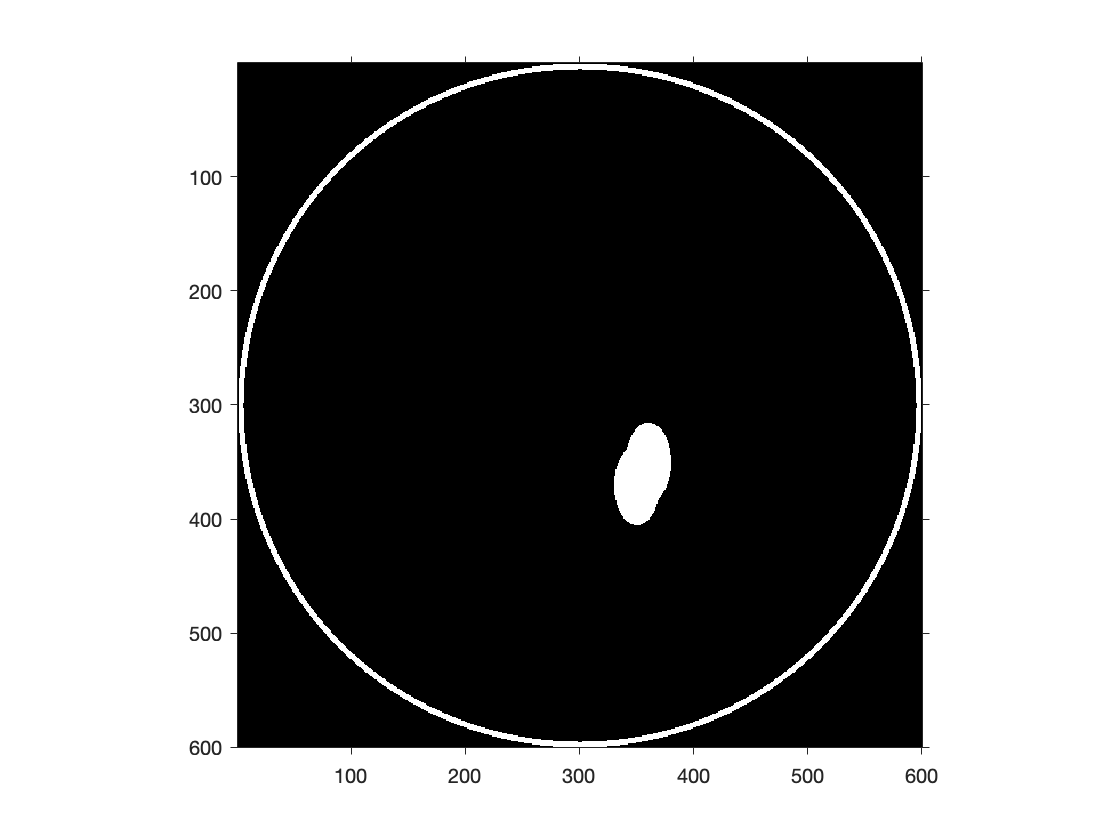

figure % Demo to show 'scanner' and object in 2 positions. Inputs x,y
d = rad ;  
E = [1 [semiaxes(1) semiaxes(2) center(1)        center(2)]/d 0 ;
     1 [semiaxes(1) semiaxes(2) center(1)+sft(1) center(2)+sft(2)]/d 0 ;
     1  rad/d       rad/d       0              0            0 ;
    -1 (rad-5)/d    (rad-5)/d   0              0            0];
P = phantom(E,rad*2);
imshow(P)

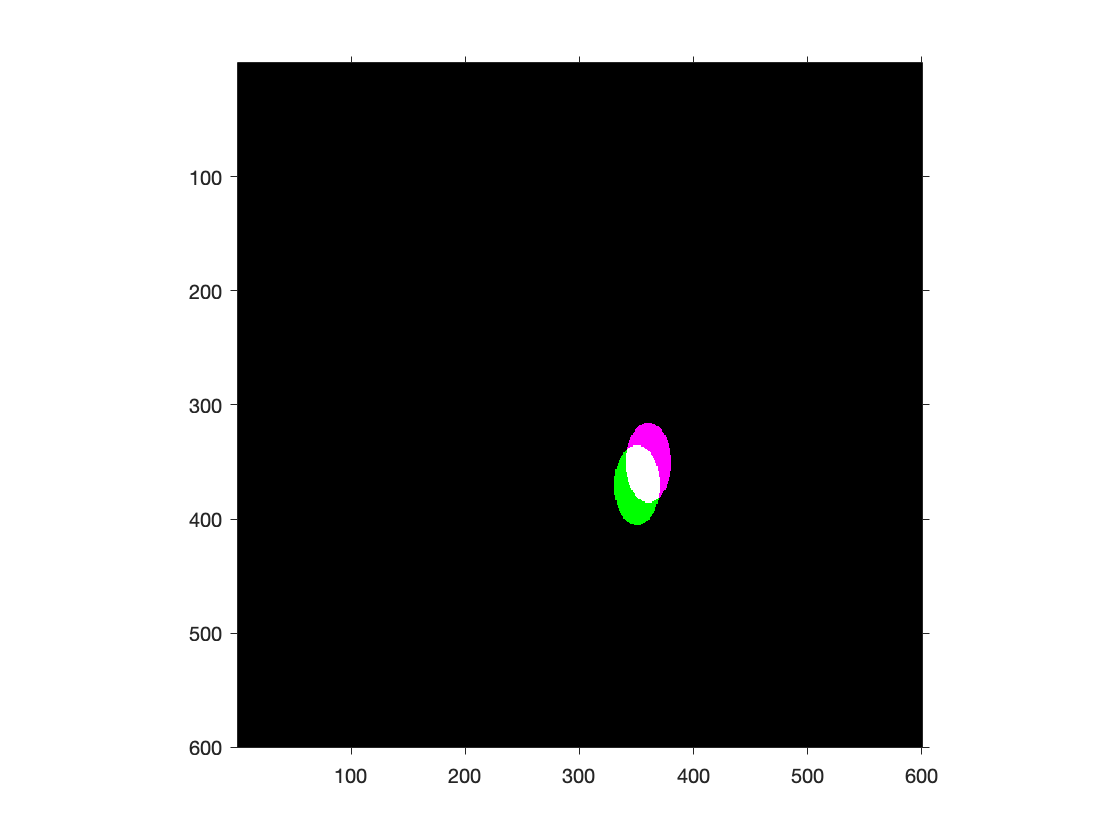


% create images for registraton without the magnet 'bore'
fixed  = phantom(E(1,:), rad*2) ;
moving = phantom(E(2,:), rad*2) ;
imshowpair(fixed, moving,'Scaling','joint')


[optimizer, metric] = imregconfig('monomodal') ;
tform = imregtform(moving, fixed, 'translation', optimizer, metric) ;
tform.T

ans =             1            0            0
            0            1            0
          -10           20            1


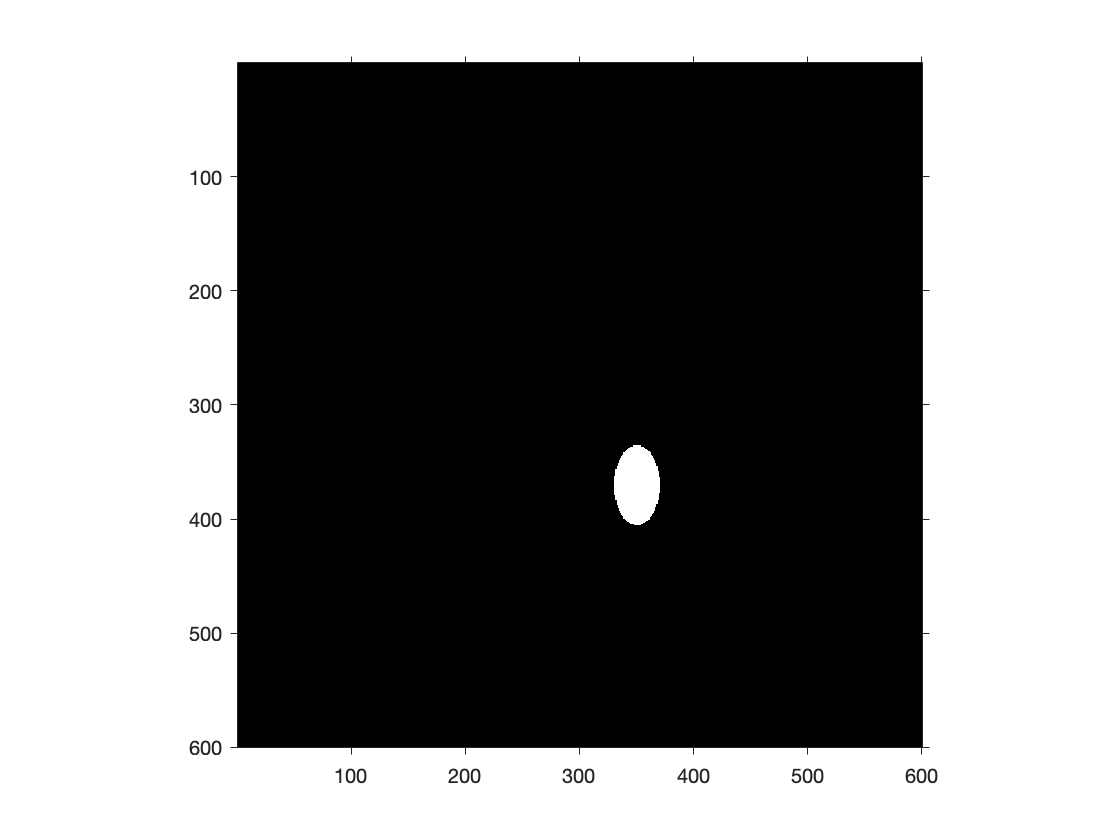

movingRegistered = imwarp(moving,tform,'OutputView',imref2d(size(fixed)));
figure ; imshowpair(fixed, movingRegistered,'Scaling','joint');

The transform has to move `moving` down to get into the space of `fixed` (green) and the value of the `tform` matrix entry for y is +20. This suggest that `tform` here refers to the intrinsic spatial coordinates.

# tform

Describe a triangle by three points (with the last repeated so that a plot closes,) and, an affine matrix representing a translation. There are two different `tform`s but both have a similar interpretation. The translations are entered as below. The `tform` from a successful registration will map `moving` to position of f`ixed `and use the intrinsic spatial coordinate system. 

U = [ 0  6  4 0] ;  % x values of input points
V = [ 0  1  7 0] ;  % y values of input points

dx = 10 ; dy = 3 ;

A = [ 1  0  0; ...
      0  1  0; ...
      dx dy 1] ;

#### `tform` ( newer class form, used with `affine2d, imwarp,` `transformPointsForward `)

tform = affine2d(A) ; 

[X, Y] = transformPointsForward(tform, U, V) 

X =     10    16    14    10


Y =      3     4    10     3


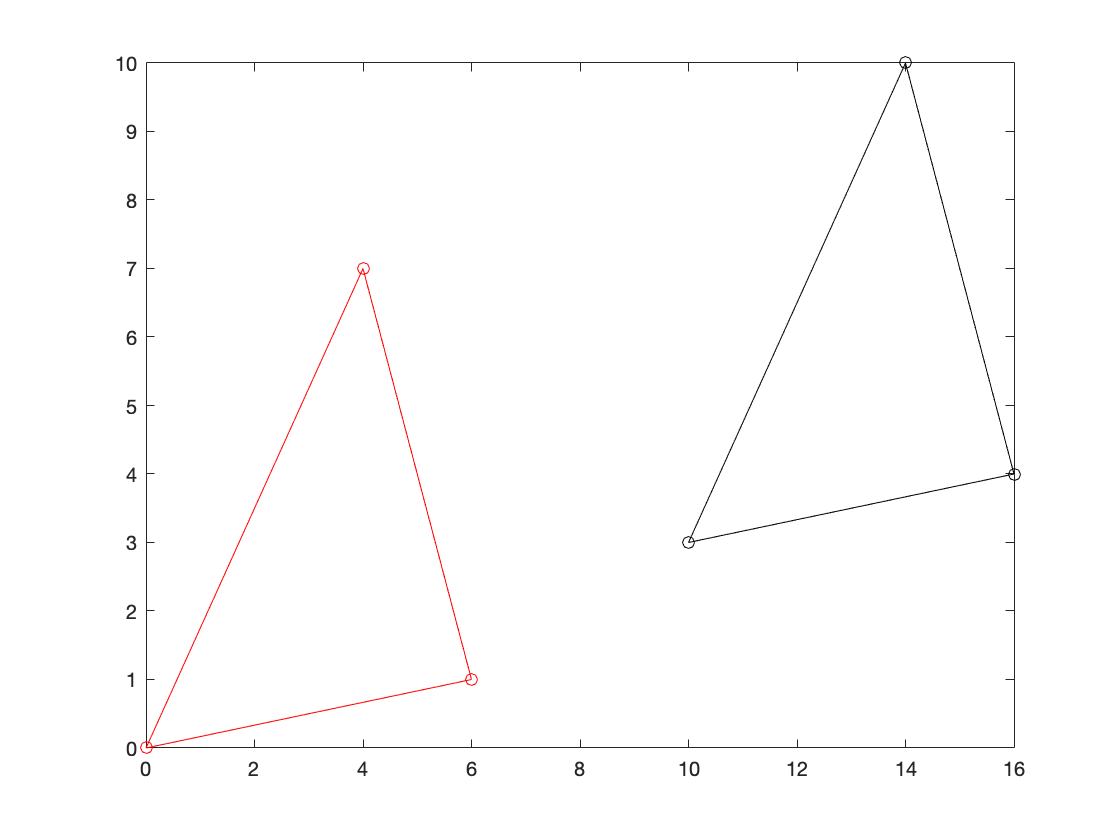


figure, plot(U,V,'ro-'), hold on, plot(X,Y,'ko-')

#### `tform` (old way, used with `maketform` and `tformfwd`)

Will not work with `imwarp`

tform = maketform('affine', A ) ;

[X, Y] = tformfwd(tform, U, V) 

X =     10    16    14    10


Y =      3     4    10     3



figure, plot(U,V,'ro-'), hold on, plot(X,Y,'ko-')

# tformarray

Uses the structure form of `tform. P`ermits use of a separable resampler, specific output points and multi-dimensions. See my code `vresample`. 

`tformarray` has a hard-to-understand set of inputs. The example below gets a rectangular patch from an image. Note that `ndgrid` and `meshgrid` behave differently for the first two dimensions.

I = imread('cameraman.tif'); % [256 256]

A = I ;
T = [ ] ; % transform empty as using tmap_B
R = makeresampler({'cubic','cubic'},'fill');
tdims_A = [1 2] ;
tdims_B = [1 2]; 
tsize_B = [] ;
F = 0 ; % fill value

samp_1 = 1:150; % 150 points
samp_2 = 100:200; % 101 points
[X1, X2] = ndgrid(samp_1,samp_2); % X1 is dim 1, which with tdims_A = [1 2] is row
tmap = cat(3,X1, X2);
size(tmap)

ans =    150   101     2


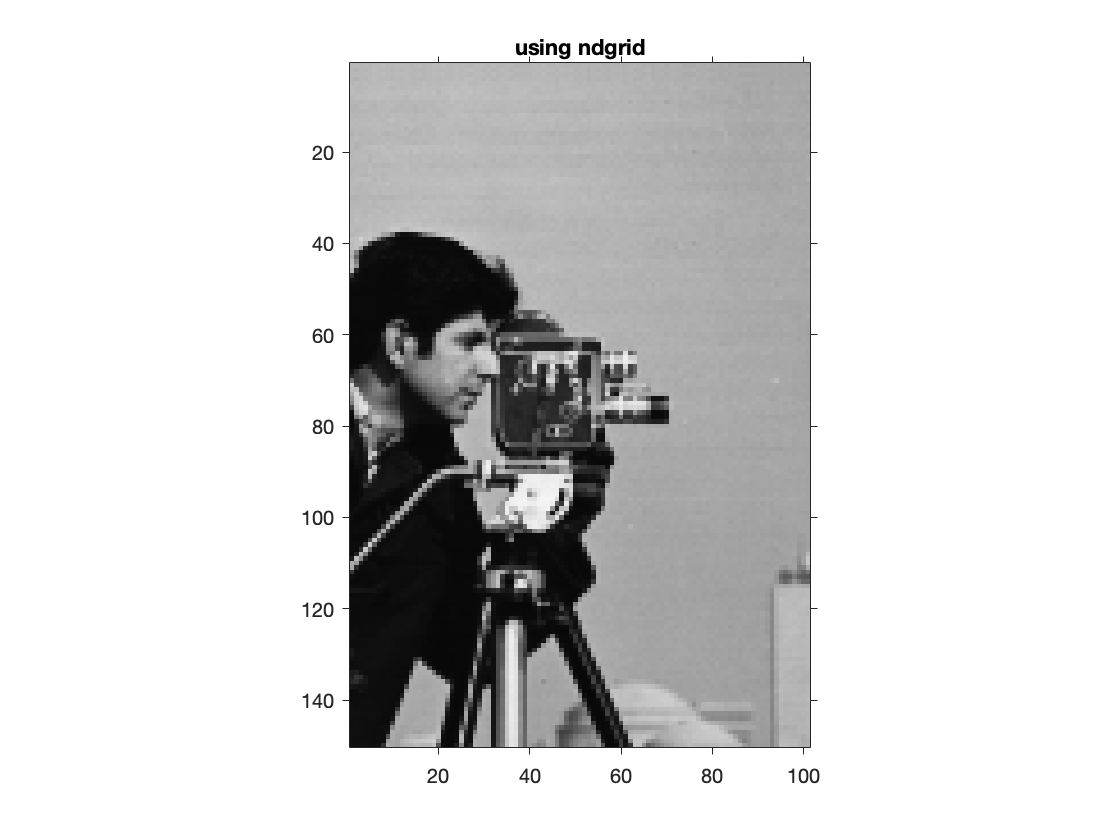

tmap_B = tmap ;

B = tformarray(A,T,R,tdims_A,tdims_B,tsize_B,tmap_B,F) ;
figure
imshow(B), title('using ndgrid')

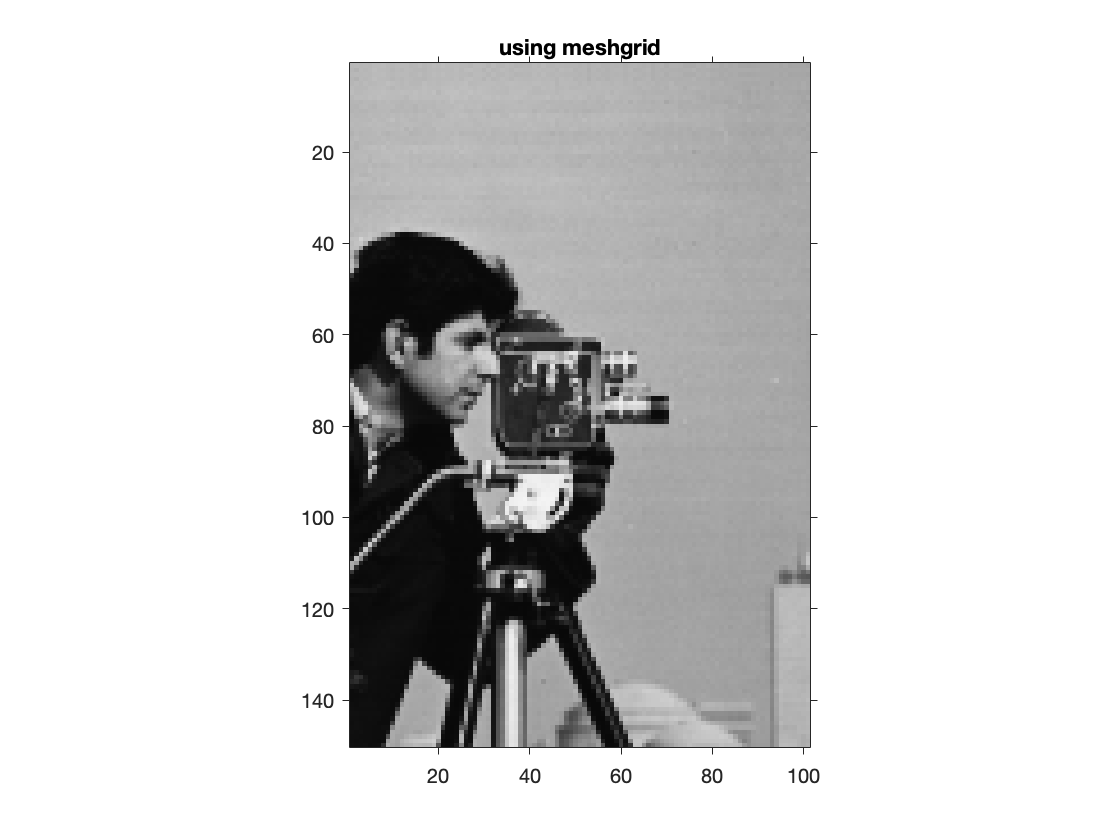


% and using meshgrid instead:
[MX, MY] = meshgrid(samp_2, samp_1) ; % Note input is xvec, yvec
tmapM = cat(3,MX,MY);
BM = tformarray(A,T,R,[2 1],tdims_B,tsize_B,tmapM,F) ; % note tdims_A [2 1] required
figure
imshow(BM), title('using meshgrid')

Look at the help "Exploring Slices from a 3-Dimensional MRI Data Set"